clc
clear

n=50

n = 50

K=6

K = 6

L=10

L = 10


m1=15;
m=[m1 m1+L m1+(2*L) m1+(3*L) m1+(4*L) m1+(5*L)]

m =     15    25    35    45    55    65


marca=m';


f=[2;10;12;14;9;3];
fr=f/n;
F=cumsum(f);
Fr=F/n;
table(marca,f,F,fr,Fr)

ans = 6×5 table
    marca    f     F      fr      Fr 
    _____    __    __    ____    ____

     15       2     2    0.04    0.04
     25      10    12     0.2    0.24
     35      12    24    0.24    0.48
     45      14    38    0.28    0.76
     55       9    47    0.18    0.94
     65       3    50    0.06       1


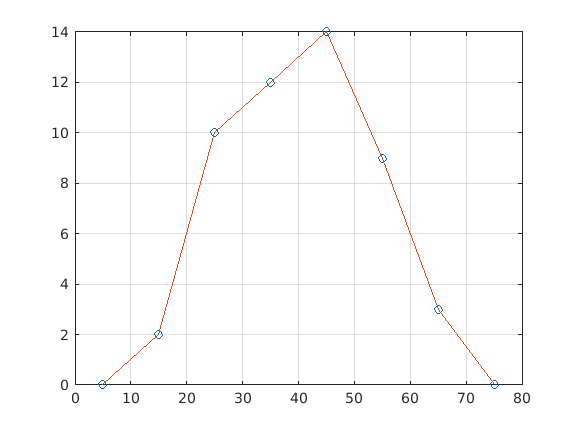

intervalo=[10:10:70];

%poligono
f=[2,10,12,14,9,3];
mp=[5 m 75];
fp=[0 f 0];
figure
plot(mp,fp,'o',mp,fp)
grid on

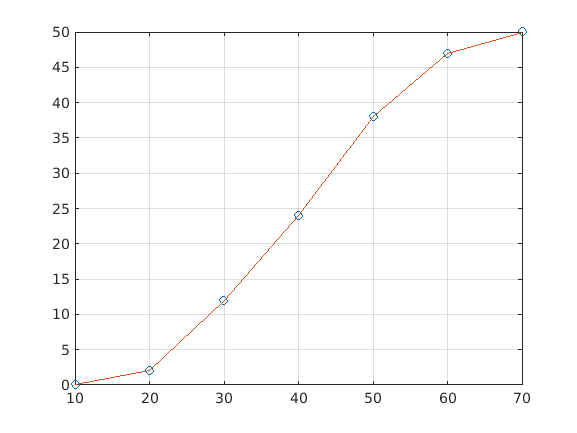


%ojiva
f_acum=cumsum(f);
FR=[0 f_acum];
figure
plot(intervalo,FR,'o',intervalo,FR)
grid on

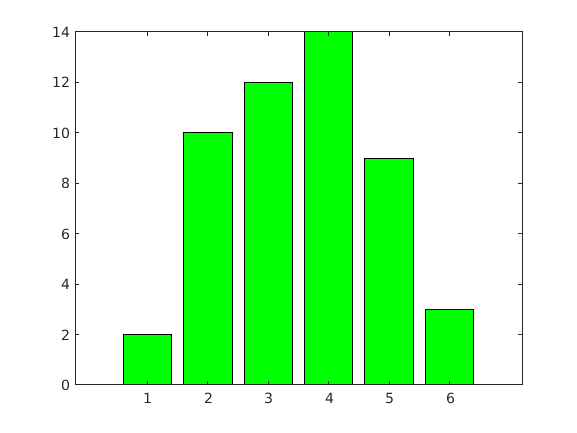


%barras
figure
bar(f,'g')

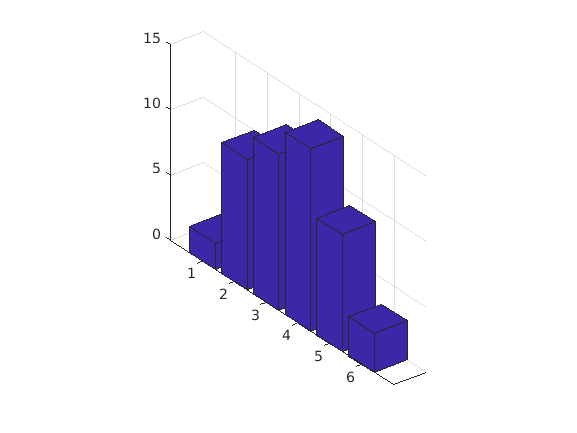

figure
bar3(f)

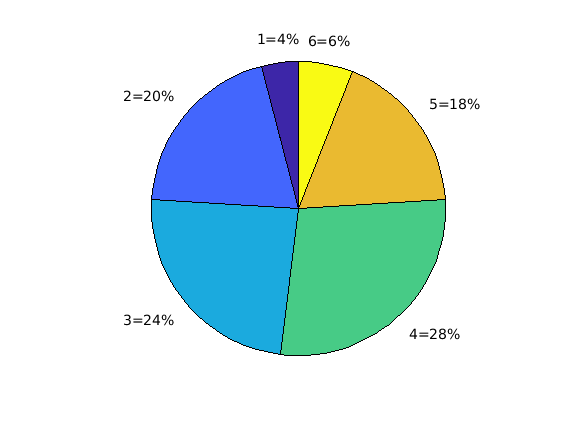


%tortas
figure
p=pie(f);
pText = findobj(p,'Type','text');
percentValues = get(pText,'String'); 
txt = {'1=';'2=';'3=';'4=';'5=';'6='}; 
combinedtxt = strcat(txt,percentValues); 
pText(1).String = combinedtxt(1);
pText(2).String = combinedtxt(2);
pText(3).String = combinedtxt(3);
pText(4).String = combinedtxt(4);
pText(5).String = combinedtxt(5);
pText(6).String = combinedtxt(6);